# **MSc Translation Neuroscience Module 3 - Workshop 1**

# **Machine Learning**

# 1. Principal Component Analysis (PCA)

### 1.1 The theory

Principal Component Analysis or PCA is a dimension reduction technique, and is one of the most basic machine learning algorithms.

The idea is to project N-dimensional data into a new p-dimensional (orthogonal) coordinate system, such that the new coordinate system maximises the variance across the data.

A visual representation of this from a 3-D dataspace to a 2-D space can be seen below:

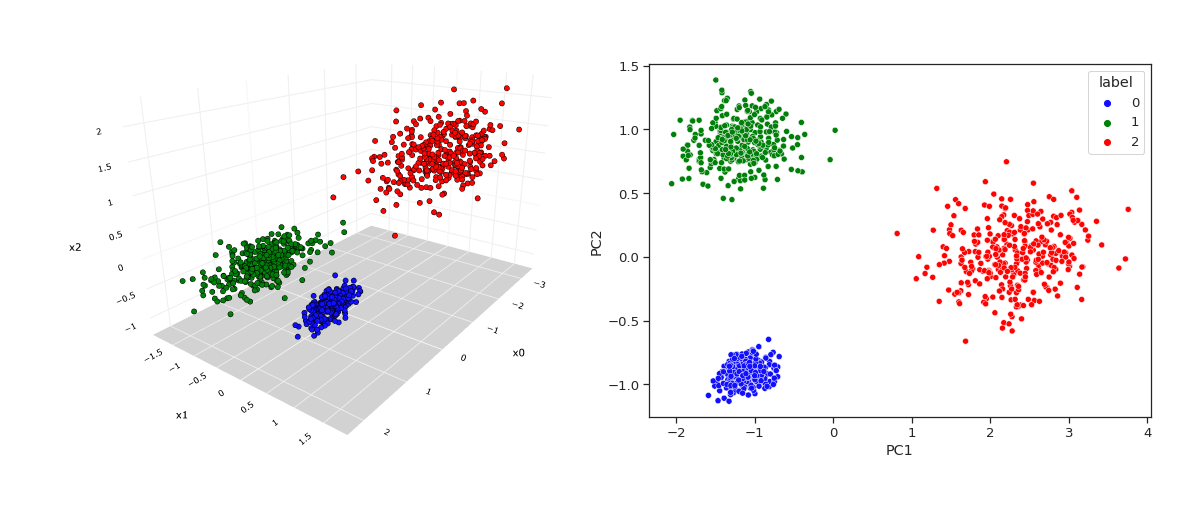

In this case, we have gone from three dimensions to two dimensions, with minimal information loss. 

If you are interested in the maths behind it, this involves eigendecomposition, and projecting your data matrix into your eigenvectors. If this doesn't make any sense to you, don't worry! If you want to learn more about it, you can read the wikipedia page on it: [https://en.wikipedia.org/wiki/Principal_component_analysis#:~:text=Principal%20component%20analysis%20(PCA)%20is,analysis%2C%20visualization%20and%20data%20preprocessing.](https://en.wikipedia.org/wiki/Principal_component_analysis#:~:text=Principal%20component%20analysis%20(PCA)%20is,analysis%2C%20visualization%20and%20data%20preprocessing.)

The reason why this is a machine learning algorithm, is because the projection axes are fully dependent on the data itself, meaning the projection weights are **learned** from the **data**.

### 1.2 Use cases

PCA is an extremely useful and widely used method of dimensionality reduction. Imagine you have patient data such as Age, Disease duration, Disease severity, Acceleration power, and Tremor score for a series of patients. Whilst these features are all different, they are not independent from one another. For example, the tremor score and acceleration power would be highly correlated. Same for the Disease duration and Disease severity. By using PCA, we could go from a 6-D feature space to a 2-D feature space, with minimal information loss. This decrease in dimensionality makes our dataset more easy to visualise, and makes it easier to handle with machine learning algorithms.

### 1.3 Implementing PCA

Let's try PCA now!

**1.3.1 Loading the data**

Let's start by loading the UPDRS data (motor impairment scores) from the PPMI dataset:

updrs = readtable("Data\UPDRS_part3.csv")

updrs = 29461×39 table
    PATNO    EVENT_ID      INFODT       NHY     PDSTATE      NP3SPCH    NP3FACXP    NP3RIGN    NP3RIGRU    NP3RIGLU    NP3RIGRL    NP3RIGLL    NP3FTAPR    NP3FTAPL    NP3HMOVR    NP3HMOVL    NP3PRSPR    NP3PRSPL    NP3TTAPR    NP3TTAPL    NP3LGAGR    NP3LGAGL    NP3RISNG    NP3GAIT    NP3FRZGT    NP3PSTBL    NP3POSTR    NP3BRADY    NP3PTRMR    NP3PTRML    NP3KTRMR    NP3KTRML    NP3RTARU    NP3RTALU

The columns starting with NP3 show the results from different UPDRS assignments. These assignments take into account things such as rigidity or tremor of different parts of the body. It is therefore likely that there is some redundancy in these, and we could use PCA to have a compact representation of our data!

**1.3.2 Applying PCA in MATLAB**

If you read the documentation of the `pca()` function, you will see that it is expecting the data as an `n x p `matrix, where `n` is the number of samples and `p `is the number of features.

Let's extract that!

*Exercise 1.1*

Extract the data from the table to have the desired dimensions. Don't include the last column (total score). You should have 33 columns in total

*Hint: Use the *`table2array()`* function to transform the sub-table to a matrix*

data = updrs(:,6:end-1);
data = table2array(data);

Let's remove invalid rows:

data = data(~any(isnan(data),2),:);

Now let's put that into PCA:

[projection_vectors, data_pca, variance_raw, ~, variance_explained] = pca(data);

As you can see, pca has many outputs. We will look at the important ones below, but for more info you can read MATLAB's documentation of the function.

% Data projected into the new axis:
disp(data_pca)

  -34.1785   -0.7199    0.9563    0.4086    1.1317   -0.1649    0.6315    0.3017    0.2272    0.3808   -0.1062    0.5617   -0.3195   -0.5590   -0.7330    0.6754   -0.2208   -0.2455   -0.6209   -0.4631    0.0778   -0.3618   -0.3698    0.1487   -0.0981    0.1730   -0.3097   -0.1344   -0.4997   -0.0046   -0.0227    0.1469   -0.0159
  -34.2727   -1.4217    0.3596    0.7026    1.5227   -0.3311    0.7915    0.1121    0.1982    0.4324   -0.0342    0.5034   -0.2297   -0.6487   -0.5024    0.0433   -0.2482    0.0361    0.0921   -0.0793    0.2249   -0.2985    0.0965    0.0933    0.0020    0.0941   -0.3172   -0.1318    0.0393   -0.1325    0.0440   -0.0065   -0.0188
  -34.2527   -1.2095    0.0173    0.5392    0.7917   -0.1119    0.1921    0.5081   -0.1447    0.0931    0.1478    0.5854    0.0601   -0.7406   -0.5420   -0.0957   -0.0997   -0.4387    0.2329   -0.9800    0.2294   -0.3128   -0.3437    0.1393   -0.1211    0.2378   -0.3519   -0.1150    0.0447   -0.0735   -0.0595   -0.0072   -0.0286
  -34.2


% Principal Component Coefficients (Loadings):
% The projection to the new axis is defined by X_pca = X*W
% where W is the projection_vectors matrix and X is the data matrix
disp(projection_vectors); % Each column is a projection vector

    0.0004    0.0129   -0.0190   -0.0085   -0.0332    0.0113   -0.0335    0.0087   -0.0128   -0.0052   -0.0090    0.0181    0.0303    0.0299    0.0040   -0.0041   -0.0293    0.0205   -0.0063    0.0329   -0.0233    0.0583    0.0119    0.0147   -0.0527    0.0257    0.9894    0.0690    0.0265   -0.0003    0.0053   -0.0026   -0.0018
    0.0031    0.0509   -0.0865   -0.0367   -0.1456    0.0394   -0.1005    0.0335   -0.0485   -0.0233   -0.0140   -0.0275    0.0247    0.0408    0.0768   -0.0464   -0.0385    0.1359   -0.0646    0.3242   -0.0954    0.8371   -0.2848    0.0461    0.0962    0.0042   -0.0767    0.0459    0.0073   -0.0074   -0.0267   -0.0016   -0.0033
    0.4077   -0.0542   -0.0080   -0.0583   -0.0313   -0.1616   -0.0056   -0.0037   -0.0086    0.0016    0.0057   -0.0056   -0.0034   -0.0157    0.0386    0.0056    0.0242    0.0152    0.0650    0.0118   -0.4946   -0.0395    0.1297    0.6868   -0.1572    0.1419   -0.0311   -0.0094    0.0011   -0.1113    0.0114   -0.0024    0.0078
    0.4

%Variance Explained by Each Principal Component (%):
for i=1:length(variance_explained)
    disp("Component: "+i+": "+round(variance_explained(i),2)+"%")
end

Component: 1: 80.9%
Component: 2: 9.4%
Component: 3: 2.16%
Component: 4: 1.25%
Component: 5: 1.13%
Component: 6: 1.01%
Component: 7: 0.72%
Component: 8: 0.51%
Component: 9: 0.43%
Component: 10: 0.38%
Component: 11: 0.26%
Component: 12: 0.24%
Component: 13: 0.2%
Component: 14: 0.18%
Component: 15: 0.17%
Component: 16: 0.15%
Component: 17: 0.14%
Component: 18: 0.12%
Component: 19: 0.1%
Component: 20: 0.08%
Component: 21: 0.07%
Component: 22: 0.07%
Component: 23: 0.06%
Component: 24: 0.05%
Component: 25: 0.04%
Component: 26: 0.04%
Component: 27: 0.03%
Component: 28: 0.03%
Component: 29: 0.02%
Component: 30: 0.02%
Component: 31: 0.02%
Component: 32: 0.02%
Component: 33: 0.01%


This shows us that over 90% of the variance in the data is explained by just the first two components, and around 98% by the first 10. This tells us that there is a lot of redundancy in our data, and allows us to have very compact representation of it, with only minimal information loss.

# 2. Classification

### 2.1 What is Classification

### 2.2 Linear Discriminant Analysis (LDA)

# 3. Evaluation

### 3.1 Accuracy

### 3.2 Confusion matrix

# 4. K-means clustering

# 5. Challenge